# ELEN 142L Lab 6 -- Ayden Dauenhauer and Alan Rieger

## Part 1: CDMA Encoding

% Step 1
n = 4;
matrix = WalshHadamard(n)

matrix =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1
     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1
     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1
     1     1     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1
     1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1
     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1     1     1
     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1     1    -1
     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1
     1    -1     1    -1     1    -1     1    -1    -1     1    -1     1    -1     1    -1     1


sum(matrix(1, :) .* matrix(3, :))

ans = 0

sum(matrix(:, 1) .* matrix(:, 3))

ans = 0

**With your n=4 matrix, how many users can your system support?**

    The n=4 matrix can support 16 users.

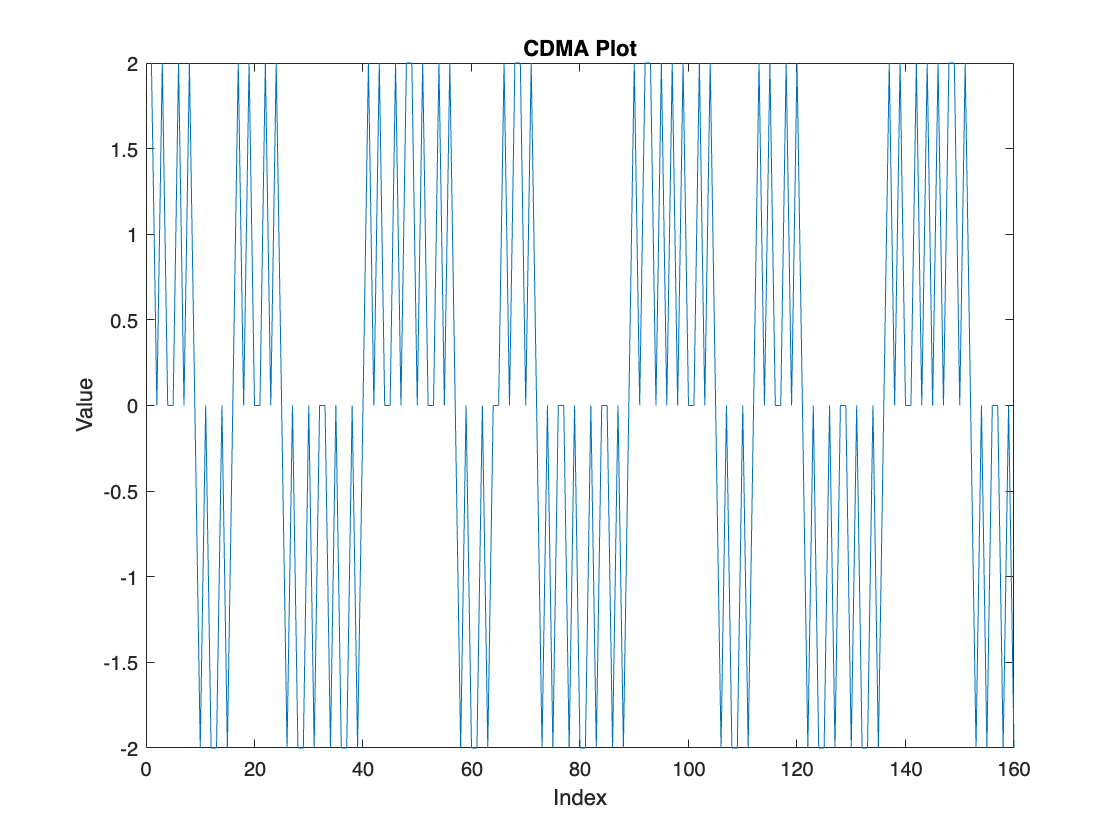

% Step 2
user1 = randi([0,1],1, 10);
user2 = randi([0,1],1, 10);
user1(user1==0) = -1;
user2(user2==0) = -1;
code1 = matrix(6, :);
code2 = matrix(9, :);
CDMA = [];
for i=1:1:10
    CDMA = [CDMA, user1(i)*code1 + user2(i)*code2];
end
figure;
plot(CDMA);
xlabel('Index');
ylabel('Value');
title('CDMA Plot');

## Part 2: CDMA Decoding

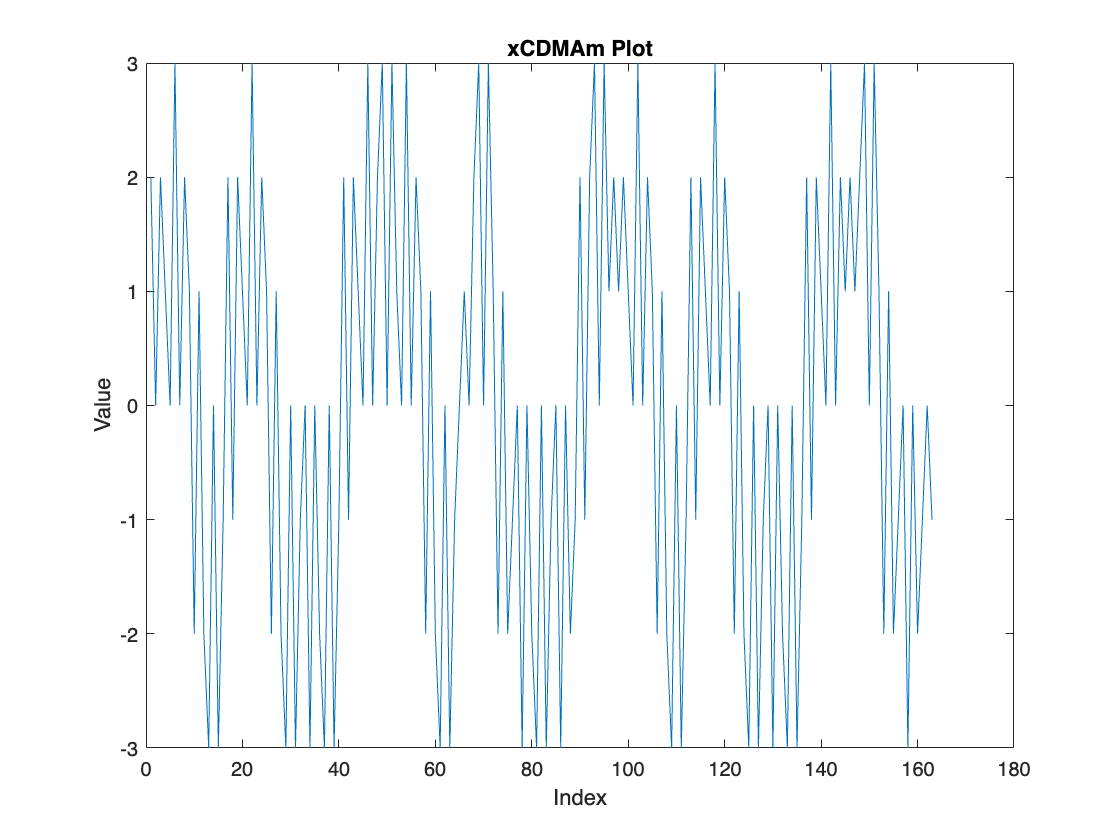

% Step 1
new_CDMA = [CDMA zeros(1, 3)];
delayed_CDMA = 0.5*[zeros(1, 3) CDMA];
xCDMA_m = new_CDMA + delayed_CDMA;
figure;
plot(xCDMA_m);
xlabel('Index');
ylabel('Value');
title('xCDMAm Plot');

**Plot the new signal and compare it against the original. What does it look like?**

    The new plot has more possible values: [-3, -2, -1, 0, 1, 2, 3], whereas the original plot has only values of [-2, 0, 2]. Also it looks shifted compared to the previous plot.

% Step 2
counter = 0;
for i=1:1:10
    rx_user1(i) = sum((xCDMA_m(1+counter*16:16+counter*16) .* code1) + (0.5*xCDMA_m(4+counter*16:19+counter*16) .* code1));
    rx_user2(i) = sum((xCDMA_m(1+counter*16:16+counter*16) .* code2) + (0.5*xCDMA_m(4+counter*16:19+counter*16) .* code2));
    counter = counter+1;
end

% Step 3
decoded_user1 = sign(rx_user1);
decoded_user2 = sign(rx_user2);
sum(decoded_user1 .* user1)

ans = 10

sum(decoded_user2 .* user2)

ans = 10

## **Part 3: Power Control**

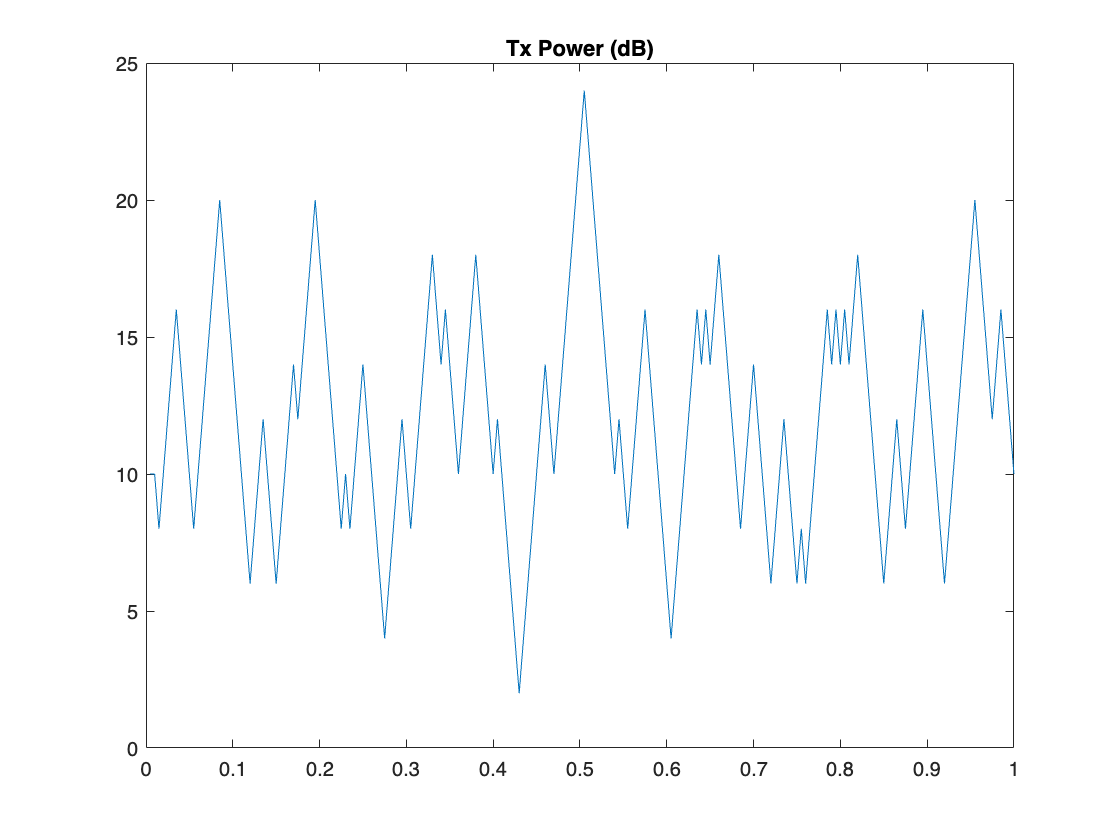

% Step 2
[timeUpdate, TxPowdB, SNRdB] = PowerControlFunc(2.4e9, 2, 5e-3);
figure;
plot(timeUpdate, TxPowdB(1:length(timeUpdate)));
title('Tx Power (dB)');

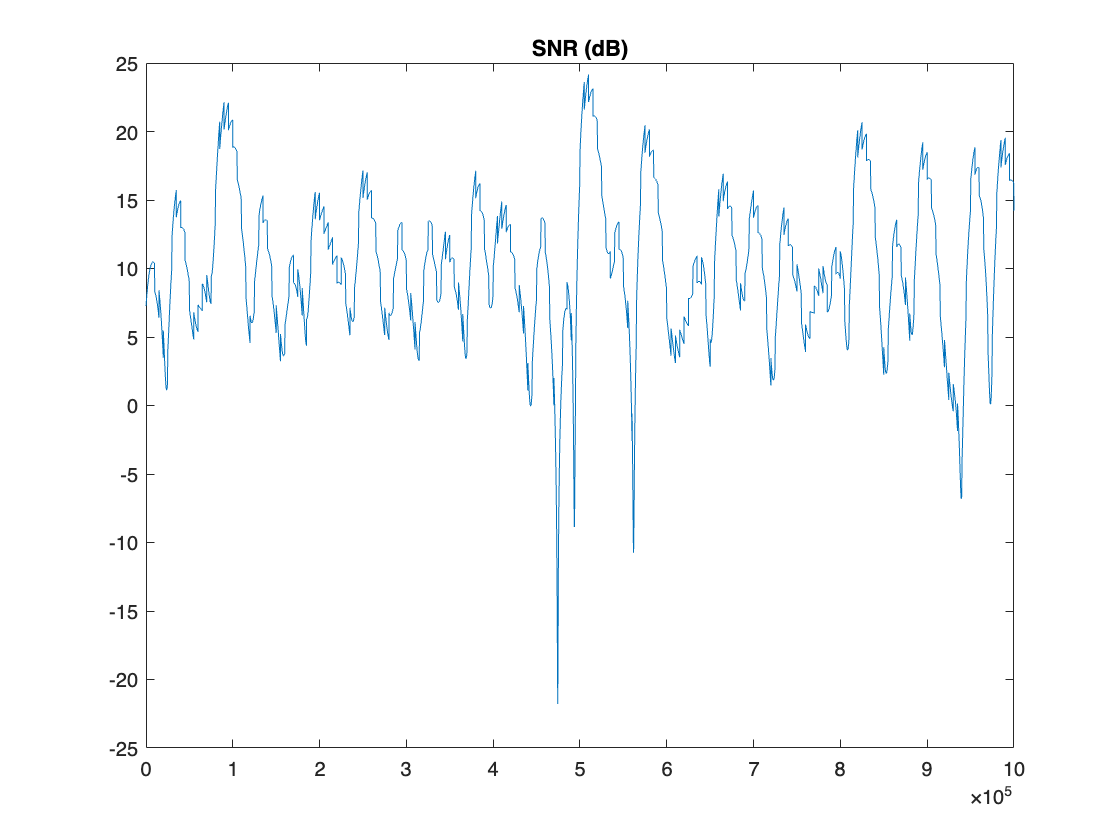

figure;
plot(SNRdB);
title('SNR (dB)');

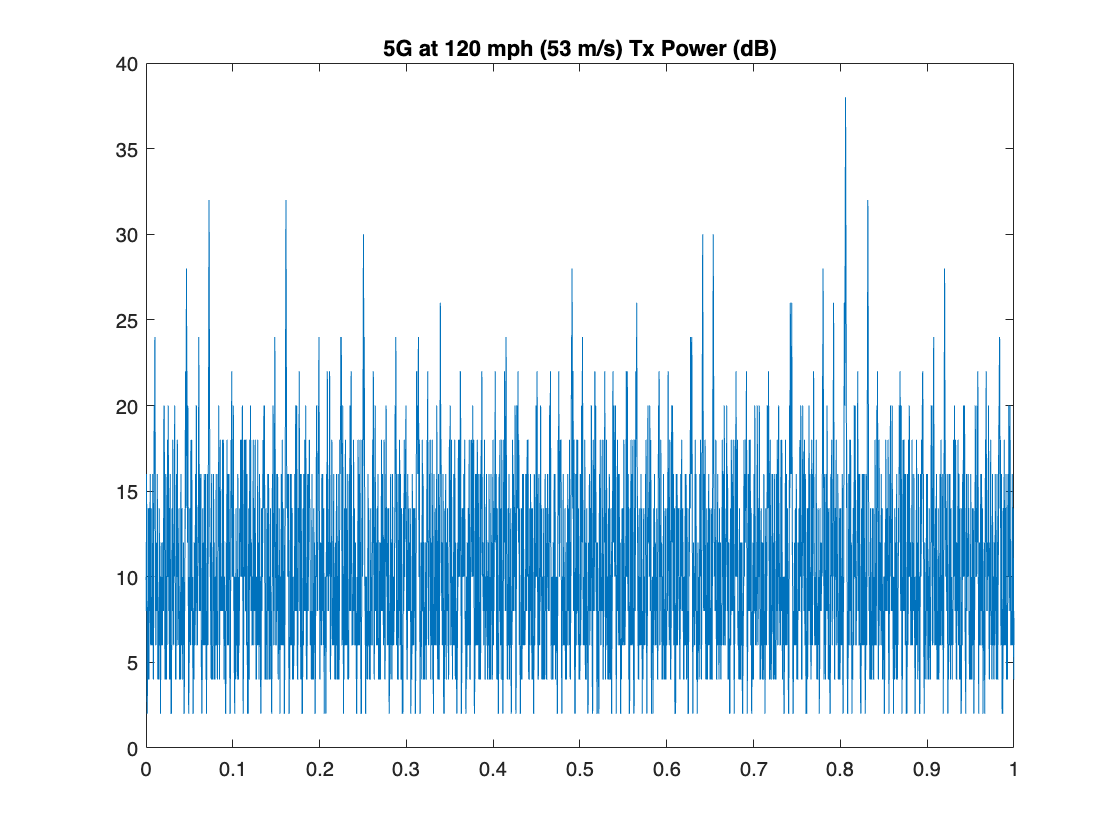

% Step 3
[timeUpdate, TxPowdB, SNRdB] = PowerControlFunc(3.0e9, 53, 1e-4);
figure;
plot(timeUpdate, TxPowdB(1:length(timeUpdate)));
title('5G at 120 mph (53 m/s) Tx Power (dB)');

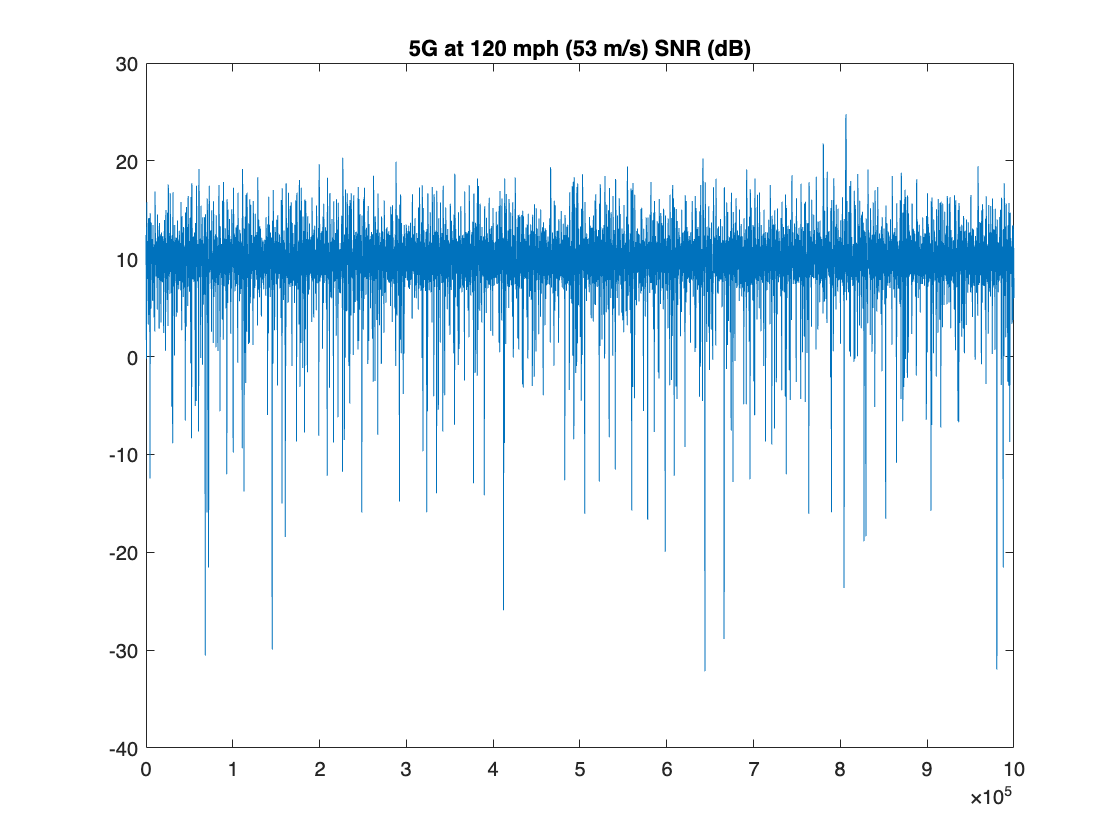

figure;
plot(SNRdB);
title('5G at 120 mph (53 m/s) SNR (dB)');

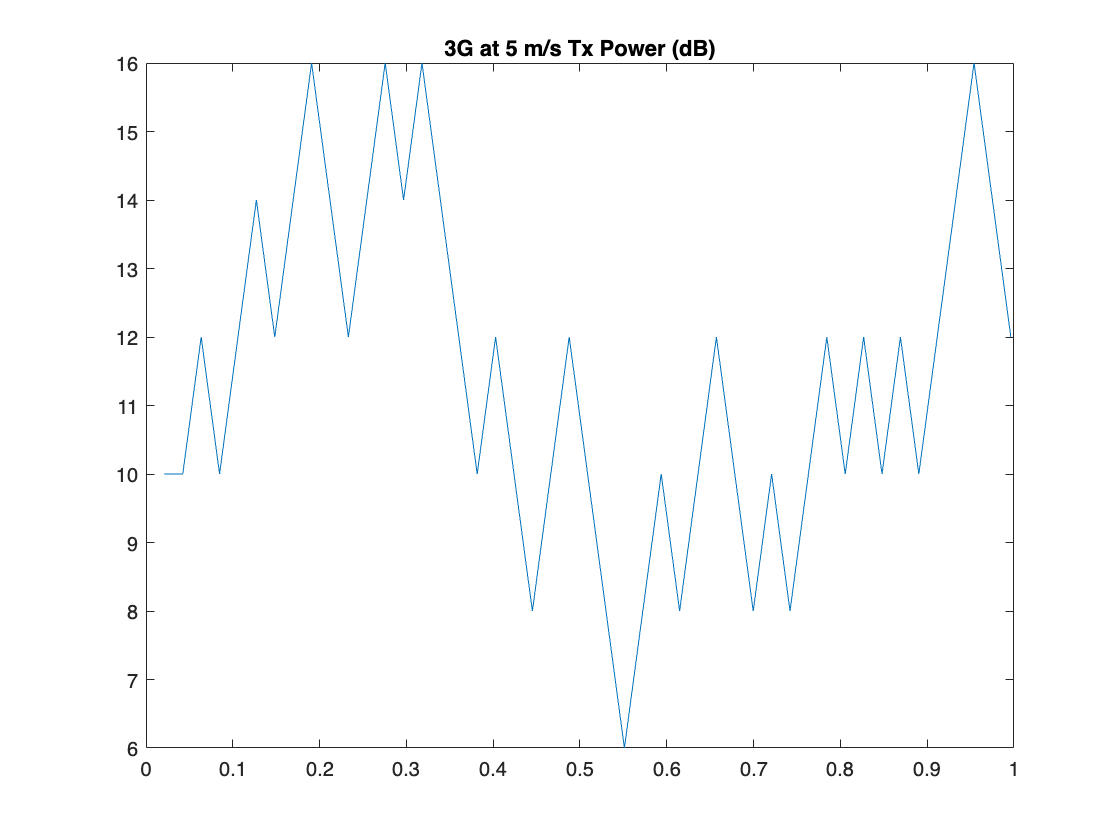

[timeUpdate, TxPowdB, SNRdB] = PowerControlFunc(2.1e9, 5, 0.0212);
figure;
plot(timeUpdate, TxPowdB(1:length(timeUpdate)));
title('3G at 5 m/s Tx Power (dB)');

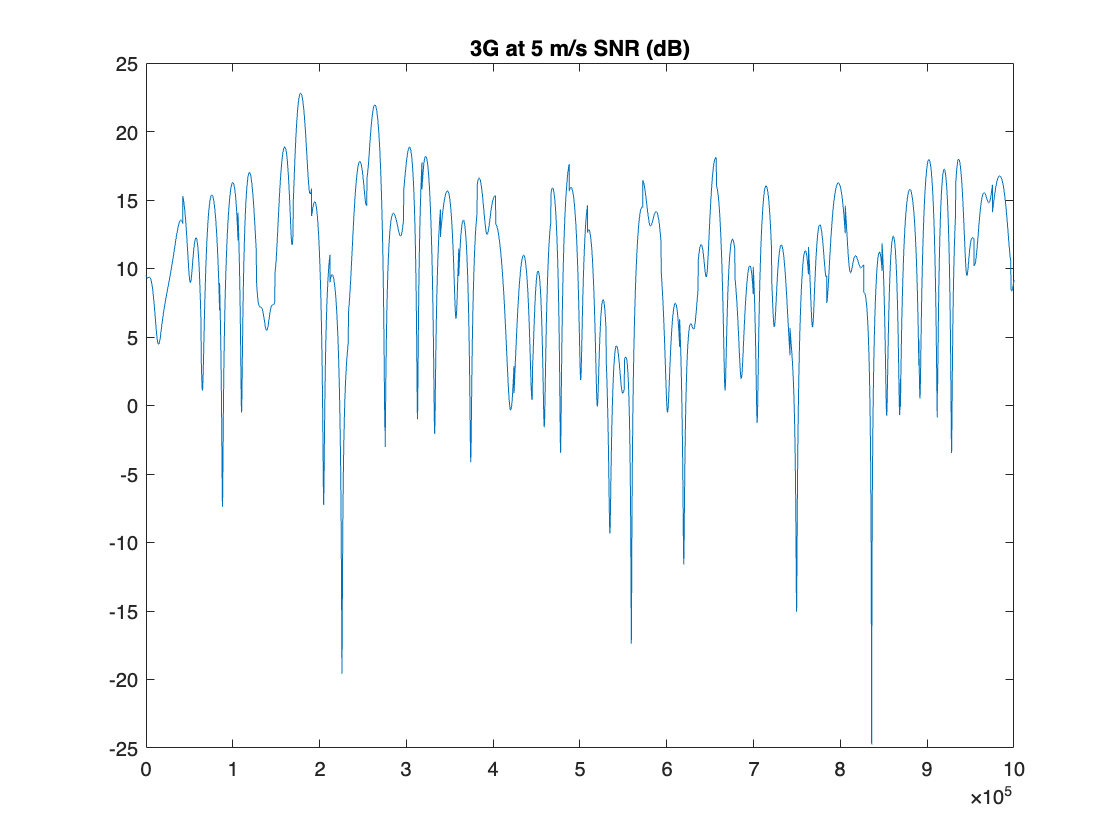

figure;
plot(SNRdB);
title('3G at 5 m/s SNR (dB)');

**Comment on your plots - do they match what you expected for the scenario you picked?**

    Yes, our first plot matches the expect 5G because there is a lot of oscillation representing a stronger signal. The last plot has less oscillations which shows a weaker signal. This is expected because 3G is weaker than 5G. Also the 5G signal has more power than both the 4G and 3G signals.

**What did you observe from the experiments?**

    We were able to visualize the signal strengths of different signals at different frequencies, latencies, and velocities. We learned how CDMA modulated a signal and how to decode it back to the original signal.

**If you could expand this experiment how would you do it?**

    We could use more scenarios for part 3. We could also use a bigger Walsh-Hadamard matrix for more users in part 1.

**How does the experiment relate to the course topic?**

    We were able to use and plot different signal srengths which we've been talking about in class with the different 1G, 2G, 3G, etc. We were also able to modulate a signal using CDMA and decode it later on which is another topic we have been discussing in class in order to more effectively transmit data.

**What did you learn from the experiment?**

    We learned how to use a Walsh-Hadamard matrix to create spreading codes which we used to modulate a signal using CDMA.